# Bases de filtrado de imágenes

## **Ruido en imágenes**

El **ruido en imágenes** se refiere a las variaciones aleatorias e indeseadas en los valores de intensidad de los píxeles, que pueden originarse por imperfecciones en los sensores, condiciones de iluminación o transmisión de datos. Este fenómeno degrada la calidad visual y puede dificultar el análisis o segmentación de estructuras dentro de la imagen.

Para **disminuir su efecto**, se aplican **técnicas de filtrado**, las cuales suavizan las variaciones abruptas de intensidad preservando, en la medida de lo posible, los bordes y detalles relevantes. Entre los métodos más comunes se encuentran los **filtros lineales** (como el promedio o el gaussiano), que reducen el ruido mediante promediado espacial, y los **filtros no lineales** (como el mediano), que son más efectivos frente a ruido impulsivo o tipo “sal y pimienta”.

Una imagen en general es la secuencia de valores de brillo que tiene una imagen. Los niveles como se ha mencioando dependen de las condiciones de iluminación y de las propiedades de absorción o reflectancia del objeto que se está fotografiando. Así, si se observa un sola línea *Columna *o *renglón *de una imagen, esta se comporta como una señal que está en función de la posición de los pixeles. 

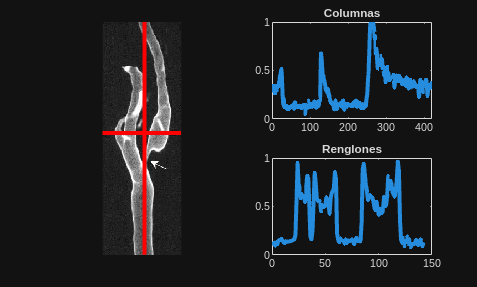

X = double(imread("/home/erit/Desktop/Imagenes/angioscan1.pgm"));
[M,N] = size(X);
X = reshape(normalize(X(:),'range'), M,N);

column = 76;
row = 201;

figure
subplot(121)
imshow(X,[])
hold on
plot([0, N],[row row],'r', 'LineWidth',3)
plot([column column],[0 M],'r', 'LineWidth',3)


subplot(222)
plot(1:M,X(:,column),'LineWidth',3);
title('Columnas')

subplot(224)
plot(1:N,X(row,:),'LineWidth',3);
title('Renglones')

## Una vista en 3D

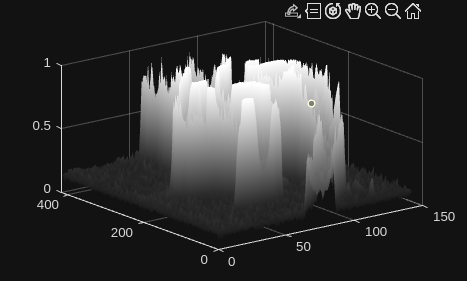

ks = 5

figure

surf(1:N,1:M,X)
colormap(gray(256));
shading interp
%[nn,mm] =  meshgrid(1:M, 1:N);
%scatter3(nn(:), mm(:), X(:), 10, X(:), 'filled')
%colorbar;

shading interp

# Filtrado lineal en 1D

El filtrado discreto en 1D es un proceso mediante el cual se modifica una señal discreta aplicando una operación de suma ponderada entre los valores pasados de la señal y de la propia salida del filtro. Este procedimiento permite resaltar o atenuar ciertas componentes en frecuencia, como ocurre al suavizar una señal ruidosa o al resaltar sus bordes.

Matemáticamente, el filtrado discreto se expresa mediante una ecuación en diferencias, que describe la salida del sistema $y[n]$ en función de la entrada $x[n]$ y de los coeficientes del filtro $b_k$ y $a_k$:


$$y[n] = \sum_{k=0}^{M-1} b_k \, x[n - k] - \sum_{k=1}^{N-1} a_k \, y[n - k]$$


donde $M$ y $N$ son el número de coeficientes asociados a la entrada y a la salida respectivamente. Esta ecuación representa un filtro lineal invariante en el tiempo, y puede describir tanto sistemas FIR (si los coeficientes $a_k$ son cero) como IIR (si los coeficientes $a_k$ son distintos de cero).

## Kernel 

En el procesamiento digital de imágenes, un \textit{kernel} o máscara de filtrado es una matriz de coeficientes que se utiliza para realizar operaciones locales sobre una imagen. Este proceso puede interpretarse como un filtrado en dos dimensiones (2D), donde la salida en cada punto depende exclusivamente de los valores de los píxeles vecinos de la imagen original, ponderados por los coeficientes del kernel.

A diferencia de los filtros recursivos (IIR), el filtrado con kernel es un proceso no recursivo o FIR (Finite Impulse Response), ya que no incluye términos de retroalimentación de la salida. Matemáticamente, el filtrado 2D se expresa como:


$$g(x, y) = \sum_{i=-a}^{a} \sum_{j=-b}^{b} h(i, j) \, f(x - i, y - j)$$


donde:

- $f(x, y)$ es la imagen de entrada,

- $g(x, y)$ es la imagen resultante,

- $h(i, j)$ representa los coeficientes del kernel o máscara,

- $2a + 1$ y $2b + 1$ son las dimensiones del kernel.

Este tipo de filtrado permite realizar operaciones como suavizado, detección de bordes o realce de detalles, dependiendo de la elección de los coeficientes $h(i, j)$.

Un kernel promediador simple de $\( 3 \times 3 \)$ puede representarse mediante una matriz en la que todos los coeficientes son iguales a 1. Este tipo de kernel calcula el valor promedio de los píxeles en una vecindad cuadrada, suavizando así la imagen. La forma general del kernel es:


$$h(i,j) = \frac{1}{9} \left[
\begin{array}{ccc}
1 & 1 & 1 \\
1 & 1 & 1 \\
1 & 1 & 1
\end{array}\right]$$


donde el factor $\frac{1}{9}$ asegura que la suma total de los coeficientes sea igual a 1, manteniendo el nivel de brillo promedio de la imagen.

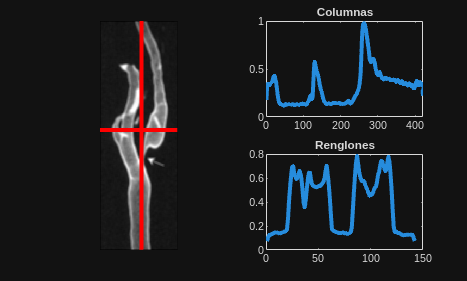

ks = 5
kernel = ones(ks);
Xfilt = (1/(ks.^2)) * conv2(X,kernel,'same');


figure
subplot(121)
imshow(Xfilt,[])
hold on
plot([0, N],[row row],'r', 'LineWidth',3)
plot([column column],[0 M],'r', 'LineWidth',3)


subplot(222)
plot(1:M,Xfilt(:,column),'LineWidth',3);
title('Columnas')


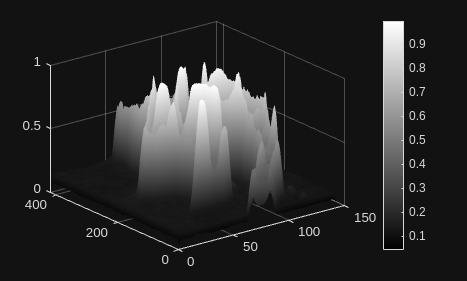

subplot(224)
plot(1:N,Xfilt(row,:),'LineWidth',3);
title('Renglones')

figure
surf(1:N, 1:M, Xfilt);

colormap(gray(256));
shading interp;
colorbar;

El tamaño y la forma del *kernel *afecta el resultado del proceso con lo que la selección del filtro depende de los resultados que se desean obtener. 

## Filtrado gaussiano

Consiste en usar a la función gaussiana como la generadora de los valores del kernel. En un primer instante, esta gaussiana es circular, es decir, se forma un gradiente simétrico que decrece de manera radial desde el centro del kernel hacia los bordes. Este tipo de filtro produce un suavizado suave y continuo, reduciendo eficazmente el ruido de alta frecuencia sin generar bordes abruptos.

En este caso, además del tamaño del kernel, se selecciona también la varianza o desviación estándar $\sigma$, que controla el ancho de la gaussiana y, por tanto, el grado de suavizado.

La función gaussiana bidimensional se expresa como:


$$G(x, y) = \frac{1}{2\pi\sigma^2} \, e^{-\frac{x^2 + y^2}{2\sigma^2}}$$


donde:

- $(x, y)$ representan las coordenadas espaciales dentro del kernel,

- $\sigma$ es la desviación estándar que determina la dispersión de la función,

- $G(x, y)$ define el peso asignado a cada píxel en función de su distancia al centro.

El resultado es un filtro de suavizado isotrópico que preserva la continuidad de las regiones de la imagen mientras reduce el ruido.

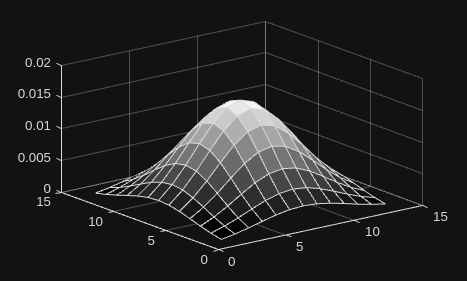

% Parámetros del filtro
tam = 13;      % tamaño del kernel (debe ser impar)
sigma = 3.3;  % desviación estándar

% Construcción del kernel gaussiano
[x, y] = meshgrid(-(tam-1)/2:(tam-1)/2, -(tam-1)/2:(tam-1)/2);
G = exp(-(x.^2 + y.^2) / (2 * sigma^2));
G = G / sum(G(:));  % normalización

% Aplicación del filtro gaussiano

X_filt = conv2(X, G, 'same');

figure
surf(1:tam,1:tam, G)
colormap("gray")

figure
subplot(121)
imshow(Xfilt,[])
hold on
plot([0, N],[row row],'r', 'LineWidth',3)
plot([column column],[0 M],'r', 'LineWidth',3)


subplot(222)
plot(1:M,Xfilt(:,column),'LineWidth',3);

title('Columnas')

subplot(224)
plot(1:N,Xfilt(row,:),'LineWidth',3);
title('Renglones')


figure
surf(1:N, 1:M, Xfilt);
colormap(gray(256));
shading interp;
colorbar;